f = @(x) exp(-x.^2)

f = function_handle with value:
    @(x)exp(-x.^2)


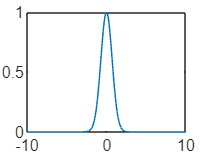

x = -10:0.1:10;
plot(x,f(x))

%Mennyire pontos a beépített integral fgv.?
integral(f,-inf,inf)-sqrt(pi)

ans = -1.2520e-10

integral(@(x)x.^2,0,1)-1/3

ans = 0

integral(@(x)sin(x),0,pi)-2

ans = -2.2204e-16

integral(@(x)exp(x),1,2)-(exp(2)-exp(1)) %Ez már nem 0.

ans = -8.8818e-16


%Trapéz szabály alkalmazása
x = -10:0.1:10;
y = f(x);
trapz(x,y) - sqrt(pi)

ans = 2.2204e-16

x = 0:0.1:10;
y = expcdf(x,2)

y =          0    0.0488    0.0952    0.1393    0.1813    0.2212    0.2592    0.2953    0.3297    0.3624    0.3935    0.4231    0.4512    0.4780    0.5034    0.5276    0.5507    0.5726    0.5934    0.6133    0.6321    0.6501    0.6671    0.6834    0.6988    0.7135    0.7275    0.7408    0.7534    0.7654    0.7769    0.7878    0.7981    0.8080    0.8173    0.8262    0.8347    0.8428    0.8504    0.8577    0.8647    0.8713    0.8775    0.8835    0.8892    0.8946    0.8997    0.9046    0.9093    0.9137


trapz(x.*y)

ans = 461.6257


x = 0:0.1:20;
y = exppdf(x,2);
trapz(x,x.*y)

ans = 1.9986


x = -10:0.1:10;
y = normpdf(x);
trapz(x,x.*y) %Szinte nulla

ans = -1.2143e-17

trapz(x,x.^2.*y)

ans = 1

t = 0:0.1:100;
t = t';
f = expcdf(t,2);
a=stint(t,f);
a(end)

ans = 1.9504

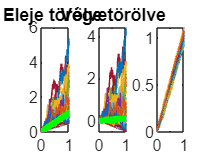

n =1000;m=100;
[w,t]=wiener(n,m);
subplot(1,3,1);
I1 = stintegral(w,w);
plot(t,I1);
title("Eleje törölve")
hold on 
plot(t,mean(I1,2),'g','LineWidth',3);
hold off
subplot(1,3,2);
I2 = stint(w,w);
plot(t,I2);
title("Vége törölve")
hold on
plot(t,mean(I2,2),"g","LineWidth",3)
hold off
subplot(1,3,3)
plot(t,mean(I1-I2,2)); %kvadratikus variáció t szerint

shg;

%Symbolic Math Toolbox kell hozzá
syms x
f = x^3
mf = matlabFunction(f)
h(3)

intf = int(f);
mf = matlabFunction(f);
mintf = matlabFunction(intf);
integral(mf,1,2) - mintf(2) - mintf(1)